clc
clear 
close all

## Functions

function res = centralDifference(u,delta_x)
    res = (u(2)-u(1))/(2*delta_x) ;
end

function res = ShuOsher(phi,psi,delta_x)
    i = 2 ;
    f_pos = 1/2*(phi(i)+phi(i+1))*(psi(i+1)-psi(i))/delta_x ;
    f_neg = 1/2*(phi(i)+phi(i-1))*(psi(i)-psi(i-1))/delta_x ;

    res = (f_pos-f_neg)/delta_x ;
end

## Constants

c_b1 = 0.1355 ;
c_b2 = 0.622 ;
sigma = 2/3 ;

## Planar Mixing Layer

% deltas
delta_y = 0.05 ;
delta_t = 1e-3 ;

% initializing space and time axes
y = -20:delta_y:20 ;
t = 0:delta_t:100 ;
iy = length(y) ;
it = length(t) ; 

% initializing arrays
u = zeros(1,iy) ;
nu_t = zeros(1,iy) ;
omega = zeros(1,iy) ;
dudt = zeros(1,iy) ;
dnu_tdt = zeros(1,iy) ;

tau_max = zeros(1,it) ;
nu_t_max = zeros(1,it) ;
omega_max = zeros(1,it) ;

% initial conditions 
nu_t(:) = 1e-8 ;
u(1:find(y==0)) = -1 ;
u(find(y==0):iy) = 1 ;

% solver loop
for i = 1:it
    % progress
    if mod(t(i), 1) == 0
        time = t(i)
    end
    
    % saving data at t = 50,100
    if i == find(t==50)
        u_50 = u ;
        nu_t_50 = nu_t ;
        yOmega_max_50 = y*omega_max(i-1) ;
        nu_tOmega_max_50 = nu_t*omega_max(i-1) ;
    elseif i == find(t==100)
        u_100 = u ;
        nu_t_100 = nu_t ;
        yOmega_max_100 = y*omega_max(i-1) ;
        nu_tOmega_max_100 = nu_t*omega_max(i-1) ;
    end
    
    % spatial loop
    for j = 2:iy-1
        omega(j) = -centralDifference(u([j-1 j+1]),delta_y) ; 
        dudt(j) = centralDifference() ;  
        dnu_tdt(j) = c_b1*abs(omega(j))*nu_t(j) + 1/sigma * ((1+c_b2)*ShuOsher(nu_t(j-1:j+1),nu_t(j-1:j+1),delta_y) - c_b2 * nu_t(j) * ShuOsher([1 1 1],nu_t(j-1:j+1),delta_y)) ;
    end
    
    % saving data at each time step
    tau_max(i) = max(abs(-nu_t.*omega)) ;
    nu_t_max(i) = max(nu_t) ;
    omega_max(i) = max(abs(omega)) ;
    
    % update
    u = u+ delta_t*dudt ;
    nu_t = nu_t + delta_t*dnu_tdt ;
end

time = 0

time = 1

time = 2

time = 3

time = 4

time = 5

time = 6

time = 7

time = 8

time = 9

time = 10

time = 11

time = 12

time = 13

time = 14

time = 15

time = 16

time = 17

time = 18

time = 19

time = 20

time = 21

time = 22

time = 23

time = 24

time = 25

time = 26

time = 27

time = 28

time = 29

time = 30

time = 31

time = 32

time = 33

time = 34

time = 35

time = 36

time = 37

time = 38

time = 39

time = 40

time = 41

time = 42

time = 43

time = 44

time = 45

time = 46

time = 47

time = 48

time = 49

time = 50

time = 51

time = 52

time = 53

time = 54

time = 55

time = 56

time = 57

time = 58

time = 59

time = 60

time = 61

time = 62

time = 63

time = 64

time = 65

time = 66

time = 67

time = 68

time = 69

time = 70

time = 71

time = 72

time = 73

time = 74

time = 75

time = 76

time = 77

time = 78

time = 79

time = 80

time = 81

time = 82

time = 83

time = 84

time = 85

time = 86

time = 87

time = 88

time = 89

time = 90

time = 91

time = 92

time = 93

time = 94

time = 95

time = 96

time = 97

time = 98

time = 99

time = 100

## Planar Mixing Layer Plots

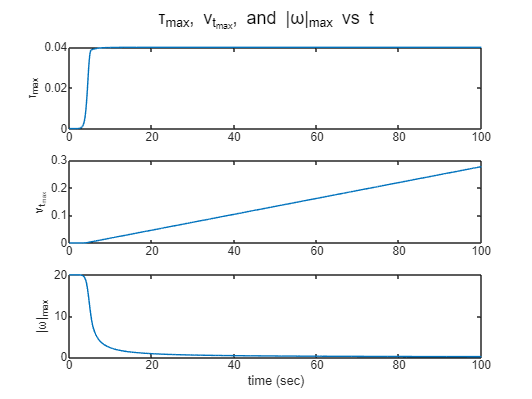

figure
subplot(3,1,1)
plot(t,tau_max)
ylabel('τ_m_a_x')
subplot(3,1,2)
plot(t,nu_t_max)
ylabel('ν_{t_m_a_x}')
subplot(3,1,3)
plot(t,omega_max)
ylabel('|ω|_m_a_x')
xlabel('time (sec)')
sgtitle('τ_m_a_x, ν_{t_m_a_x}, and |ω|_m_a_x vs t')

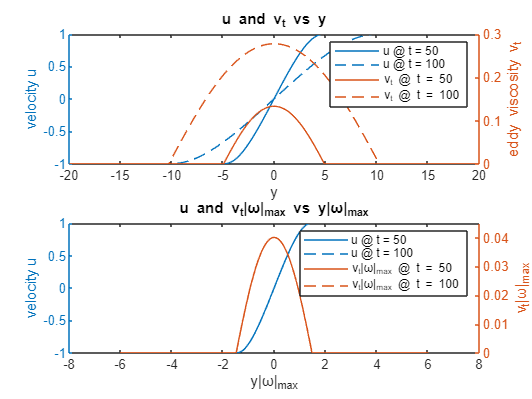


figure
subplot(2,1,1)
yyaxis left
plot(y,u_50,y,u_100)
ylabel('velocity u')
yyaxis right
plot(y,nu_t_50,y,nu_t_100)
ylabel('eddy viscosity ν_t')
legend('u @ t = 50','u @ t = 100','ν_t @ t = 50','ν_t @ t = 100')
xlabel('y')
title('u and ν_t vs y')
subplot(2,1,2)
yyaxis left
plot(yOmega_max_50,u_50,yOmega_max_100,u_100)
ylabel('velocity u')
yyaxis right
plot(yOmega_max_50,nu_tOmega_max_50,yOmega_max_100,nu_tOmega_max_100)
ylabel('ν_t|ω|_m_a_x')
legend('u @ t = 50','u @ t = 100','ν_t|ω|_m_a_x @ t = 50','ν_t|ω|_m_a_x @ t = 100')
xlabel('y|ω|_m_a_x')
title('u and ν_t|ω|_m_a_x vs y|ω|_m_a_x')

## Planar Wake

% deltas
delta_y = 0.05 ;
delta_t = 5e-3 ;

% initializing space and time axes
y = -25:delta_y:25 ;
t = 0:delta_t:3000 ;
iy = length(y) ;
it = length(t) ; 

% initializing arrays
nu_t = zeros(1,iy) ;
omega = zeros(1,iy) ;
dudt = zeros(1,iy) ;
dnu_tdt = zeros(1,iy) ;

tau_max = zeros(1,it) ;
nu_t_max = zeros(1,it) ;
omega_max = zeros(1,it) ;
u_deficit_max = zeros(1,it) ;

% initial conditions 
nu_t(:) = 1e-5 ;
u = 1 - exp(-25.*y.^2) ;

% solver loop
for i = 1:it
    % progress
    if mod(t(i), 50) == 0
        time = t(i)
    end
    
    % saving data at t = 1500,3000
    if i == find(t==1500)
        u_1500 = u ;
        nu_t_1500 = nu_t ;
    elseif i == find(t==3000)
        u_3000 = u ;
        nu_t_3000 = nu_t ;
    end
    
    % spatial loop
    for j = 2:iy-1
        omega(j) = -centralDifference(u([j-1 j+1]),delta_y) ; 
        dudt(j) = ShuOsher(nu_t(j-1:j+1),u(j-1:j+1),delta_y) ;  
        dnu_tdt(j) = c_b1*abs(omega(j))*nu_t(j) + 1/sigma * ((1+c_b2)*ShuOsher(nu_t(j-1:j+1),nu_t(j-1:j+1),delta_y) - c_b2 * nu_t(j) * ShuOsher([1 1 1],nu_t(j-1:j+1),delta_y)) ;
    end
    
    % saving data at each time step
    tau_max(i) = max(abs(-nu_t.*omega)) ;
    nu_t_max(i) = max(nu_t) ;
    omega_max(i) = max(abs(omega)) ;
    u_deficit_max(i) = max(1-u) ;
    
    % update
    u = u+ delta_t*dudt ;
    nu_t = nu_t + delta_t*dnu_tdt ;
end

time = 0

time = 50

time = 100

time = 150

time = 200

time = 250

time = 300

time = 350

time = 400

time = 450

time = 500

time = 550

time = 600

time = 650

time = 700

time = 750

time = 800

time = 850

time = 900

time = 950

time = 1000

time = 1050

time = 1100

time = 1150

time = 1200

time = 1250

time = 1300

time = 1350

time = 1400

time = 1450

time = 1500

time = 1550

time = 1600

time = 1650

time = 1700

time = 1750

time = 1800

time = 1850

time = 1900

time = 1950

time = 2000

time = 2050

time = 2100

time = 2150

time = 2200

time = 2250

time = 2300

time = 2350

time = 2400

time = 2450

time = 2500

time = 2550

time = 2600

time = 2650

time = 2700

time = 2750

time = 2800

time = 2850

time = 2900

time = 2950

time = 3000

## Planar Wake Plots

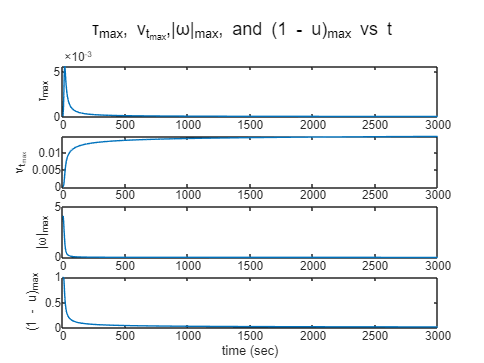

figure
subplot(4,1,1)
plot(t,tau_max)
ylabel('τ_m_a_x')
subplot(4,1,2)
plot(t,nu_t_max)
ylabel('ν_{t_m_a_x}')
subplot(4,1,3)
plot(t,omega_max)
ylabel('|ω|_m_a_x')
subplot(4,1,4)
plot(t,u_deficit_max)
ylabel('(1 - u)_m_a_x')
xlabel('time (sec)')
sgtitle('τ_m_a_x, ν_{t_m_a_x},|ω|_m_a_x, and (1 - u)_m_a_x vs t')

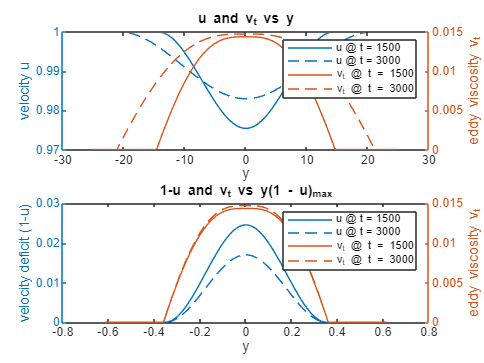

figure
subplot(2,1,1)
yyaxis left
plot(y,u_1500,y,u_3000)
ylabel('velocity u')
yyaxis right
plot(y,nu_t_1500,y,nu_t_3000)
ylabel('eddy viscosity ν_t')
legend('u @ t = 1500','u @ t = 3000','ν_t @ t = 1500','ν_t @ t = 3000')
xlabel('y')
title('u and ν_t vs y')
subplot(2,1,2)
yyaxis left
plot(y*u_deficit_max(t==1500),1-u_1500,y*u_deficit_max(t==3000),1-u_3000)
ylabel('velocity deficit (1-u)')
yyaxis right
plot(y*u_deficit_max(t==1500),nu_t_1500,y*u_deficit_max(t==3000),nu_t_3000)
ylabel('eddy viscosity ν_t')
legend('u @ t = 1500','u @ t = 3000','ν_t @ t = 1500','ν_t @ t = 3000')
xlabel('y')
title('1-u and ν_t vs y(1 - u)_m_a_x')

## Mature Vortex

% deltas
delta_r = 0.2 ;
delta_t = 5e-3 ;

% initializing space and time axes
r = 0:delta_r:100 ;
t = 0:delta_t:2000 ;
ir = length(r) ;
it = length(t) ; 

% initializing arrays
nu_t = zeros(1,ir) ;
omega = zeros(1,ir) ;
dudt = zeros(1,ir) ;
dnu_tdt = zeros(1,ir) ;

tau_max = zeros(1,it) ;
nu_t_max = zeros(1,it) ;
omega_max = zeros(1,it) ;
u_deficit_max = zeros(1,it) ;

% initial conditions 
nu_t(:) = 1e-5 ;
u = 1 - exp(-25.*y.^2) ;

% solver loop
for i = 1:it
    % progress
    if mod(t(i), 50) == 0
        time = t(i)
    end
    
    % saving data at t = 1500,3000
    if i == find(t==1500)
        u_1500 = u ;
        nu_t_1500 = nu_t ;
    elseif i == find(t==3000)
        u_3000 = u ;
        nu_t_3000 = nu_t ;
    end
    
    % spatial loop
    for j = 2:ir-1
        omega(j) = 1/r(j)*centralDifference([r(j-1) r(j+1)].*u([j-1 j+1]),delta_r) ; 
        dudt(j) = centralDifference(r(j)^2*nu(j)*(centralDifference())) ;  
        dnu_tdt(j) = c_b1*abs(omega(j))*nu_t(j) + 1/sigma * ((1+c_b2)*ShuOsher(nu_t(j-1:j+1),nu_t(j-1:j+1),delta_r) - c_b2 * nu_t(j) * ShuOsher([1 1 1],nu_t(j-1:j+1),delta_r)) ;
    end
    
    % saving data at each time step
    tau_max(i) = max(abs(-nu_t.*omega)) ;
    nu_t_max(i) = max(nu_t) ;
    omega_max(i) = max(abs(omega)) ;
    u_deficit_max(i) = max(1-u) ;
    
    % update
    u = u+ delta_t*dudt ;
    nu_t = nu_t + delta_t*dnu_tdt ;
end